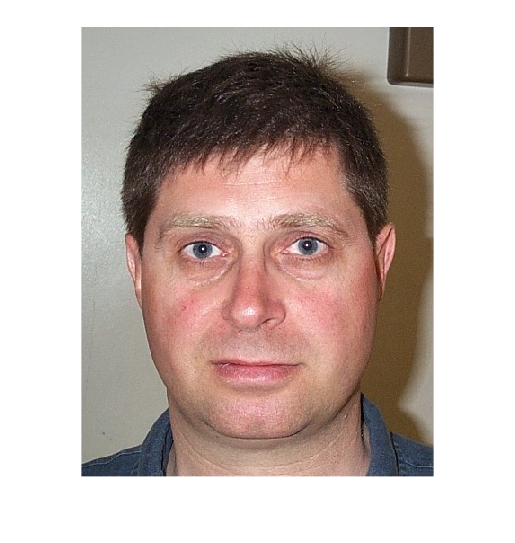

clear
im = imread("DB1\TestMedRotation301.jpg");
cropbildtest = (im);
imtest = imread("DB1\db1_01.jpg");
imshow("DB1\db1_01.jpg");


gim = rgb2gray(im);

immin = min(gim)

immin = 1×316 uint8 row vector
   50   52   48   19   27   32   31   30   23   13   25   23   26   22   26   19   16   14   34   58   82   59   36   37   37   33   27   36   27   28   26   23   24   21   21   15   19   21   21   21   19   21   25   21   24   21   18   23   15   24


immax = max(gim)

immax = 1×316 uint8 row vector
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255


imsize = length(im)

imsize = 396

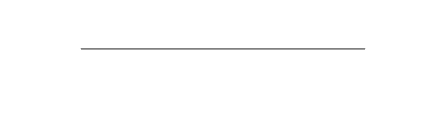


for ii=1:imsize
    normIm = (imtest(ii) - immin)./(immax - immin);
end
imshow(normIm);

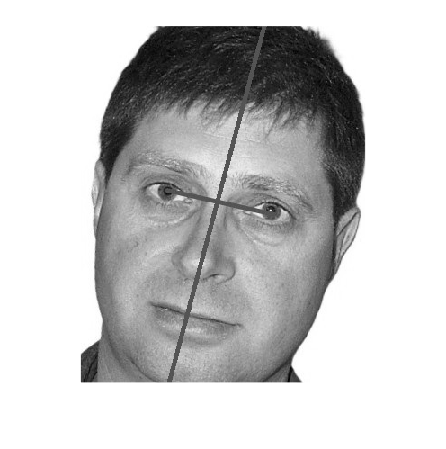

imshow(gim)

%öga 1 = (
a1 = 250;
a2 = 230;
b1 = 100;
b2 = 270;
crop = gim;

BW = edge(crop,'canny');

[H,T,R] = hough(BW,'RhoResolution',0.5,'Theta',-90:0.5:89);

maxH = max(H(:));                  
[row, col] = find(H == maxH);

theta_max = T(col);                

disp(theta_max);                   

    15





rotDeg = -(theta_max); 
disp(rotDeg);

   -15



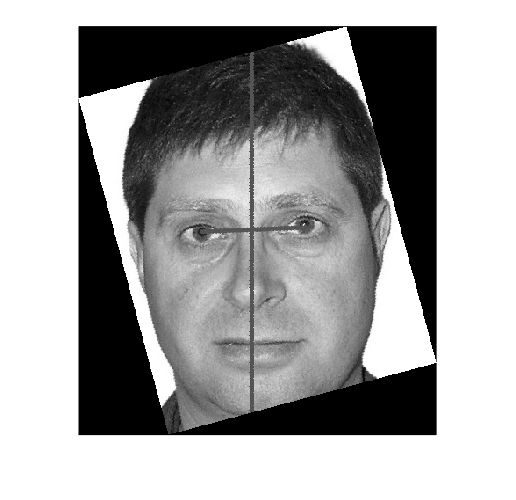


Rotatedback = imrotate(crop,theta_max);
imshow(Rotatedback)

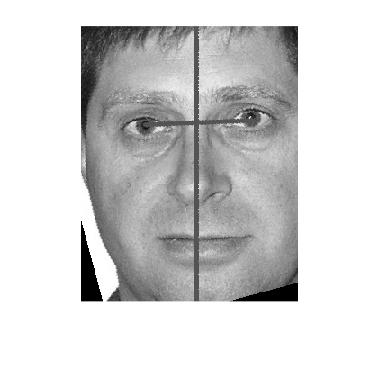


%cropped_img = crop(row_start:row_end, col_start:col_end, :);
cropped_img2 = Rotatedback(a1 - 125 :a2 + 200, b1 - 30:b2 +40, :);

%imshow(cropped_img)
imshow(cropped_img2)